%% =========================================================
%  TALLER 2 – Análisis de Incertidumbre en Ingeniería Civil
%  2026-1S | Universidad Nacional de Colombia
%  Departamento de Ingeniería Civil y Agrícola
% =========================================================
clc; clear; close all;

%% -------------------------------------------------------
%  DATOS: número de terremotos por año (1900-1999)
%  magnitud >= 7.0
% -------------------------------------------------------
T = [13,14, 8,10,16,26,32,27,18,32, ...  % 1900-1909
     36,24,22,23,22,18,25,21,21,14, ...  % 1910-1919
      8,11,14,23,18,17,19,20,22,19, ...  % 1920-1929
     13,26,13,14,22,24,21,22,26,21, ...  % 1930-1939
     23,24,27,41,31,27,35,26,28,36, ...  % 1940-1949
     39,21,17,22,17,19,15,34,10,15, ...  % 1950-1959
     22,18,15,20,15,22,19,16,30,27, ...  % 1960-1969
     29,23,20,16,21,21,16,16,18,15, ...  % 1970-1979
     18,14,10,15, 8,15, 6,11, 8, 7, ...  % 1980-1989
     13,10,23,16,15,25,22,20,16,20];     % 1990-1999

n = length(T);   % n = 100 años

%% =======================================================
%  PREGUNTA 1: Media y desviación estándar poblacional
% =======================================================
mu_T    = mean(T);
sigma_T = std(T, 1);   % std con N (poblacional)

fprintf('============================================\n');

fprintf(' PREGUNTA 1\n');

 PREGUNTA 1


fprintf('============================================\n');

fprintf(' mu_T    = %.4f terremotos/año\n', mu_T);

 mu_T    = 19.9300 terremotos/año


fprintf(' sigma_T = %.4f terremotos/año\n', sigma_T);

 sigma_T = 7.1837 terremotos/año


fprintf('\n');

%% =======================================================
%  PREGUNTA 2: P(X=2 terremotos en un mes) – Binomial
% =======================================================
%  p = mu_T/365 : prob de terremoto en un día
%  n_mes = 30 días (un mes)
%  X ~ Binomial(n=30, p)
% -------------------------------------------------------
p       = mu_T / 365;
n_mes   = 30;
k2      = 2;

P_bin_2 = nchoosek(n_mes, k2) * p^k2 * (1-p)^(n_mes - k2);

fprintf('============================================\n');

fprintf(' PREGUNTA 2 – Modelo Binomial\n');

 PREGUNTA 2 – Modelo Binomial


fprintf('============================================\n');

fprintf(' p = mu_T/365 = %.6f\n', p);

 p = mu_T/365 = 0.054603


fprintf(' X ~ Binomial(n=%d, p=%.6f)\n', n_mes, p);

 X ~ Binomial(n=30, p=0.054603)


fprintf(' P(X = 2 | mes) = %.6f\n', P_bin_2);

 P(X = 2 | mes) = 0.269228


fprintf('\n');

%% =======================================================
%  PREGUNTA 3: P(primer terremoto ocurre el día 15)
%  Y ~ Geométrica(p)  →  P(Y=k) = (1-p)^(k-1) * p
% =======================================================
k3   = 15;
P_geo_15 = (1-p)^(k3-1) * p;

fprintf('============================================\n');

fprintf(' PREGUNTA 3 – Distribución Geométrica\n');

 PREGUNTA 3 – Distribución Geométrica


fprintf('============================================\n');

fprintf(' Y ~ Geométrica(p=%.6f)\n', p);

 Y ~ Geométrica(p=0.054603)


fprintf(' P(Y = 15) = (1-p)^14 * p = %.6f\n', P_geo_15);

 P(Y = 15) = (1-p)^14 * p = 0.024878


fprintf('\n');

%% =======================================================
%  PREGUNTA 4: E[Y] y sigma_Y – tiempo hasta 1er terremoto
%  Y ~ Geométrica(p)
%  E[Y] = 1/p
%  sigma_Y = sqrt(1-p) / p
% =======================================================
E_Y     = 1 / p;
sigma_Y = sqrt(1-p) / p;

fprintf('============================================\n');

fprintf(' PREGUNTA 4 – Valor esperado y desv. estándar\n');

 PREGUNTA 4 – Valor esperado y desv. estándar


fprintf('============================================\n');

fprintf(' E[Y]     = 1/p          = %.4f días\n', E_Y);

 E[Y]     = 1/p          = 18.3141 días


fprintf(' sigma_Y  = sqrt(1-p)/p  = %.4f días\n', sigma_Y);

 sigma_Y  = sqrt(1-p)/p  = 17.8071 días


fprintf('\n');

%% =======================================================
%  PREGUNTA 5: P(2do terremoto ocurre el día 30)
%  W_r ~ Binomial Negativa (Pascal), r=2, k=30
%  P(W_2 = k) = C(k-1, r-1) * p^r * (1-p)^(k-r)
% =======================================================
r5   = 2;
k5   = 30;
P_NB_30 = nchoosek(k5-1, r5-1) * p^r5 * (1-p)^(k5-r5);

fprintf('============================================\n');

fprintf(' PREGUNTA 5 – Binomial Negativa (Pascal r=2)\n');

 PREGUNTA 5 – Binomial Negativa (Pascal r=2)


fprintf('============================================\n');

fprintf(' W_2 ~ Pascal(r=2, p=%.6f)\n', p);

 W_2 ~ Pascal(r=2, p=0.054603)


fprintf(' P(W_2 = 30) = C(29,1)*p^2*(1-p)^28 = %.6f\n', P_NB_30);

 P(W_2 = 30) = C(29,1)*p^2*(1-p)^28 = 0.017949


fprintf('\n');

%% =======================================================
%  PREGUNTA 6: E[W_4] – días hasta el 4to terremoto
%  W_r ~ Pascal(r, p)  →  E[W_r] = r/p
% =======================================================
r6    = 4;
E_W4  = r6 / p;

fprintf('============================================\n');

fprintf(' PREGUNTA 6 – Días esperados hasta 4 terremotos\n');

 PREGUNTA 6 – Días esperados hasta 4 terremotos


fprintf('============================================\n');

fprintf(' W_4 ~ Pascal(r=4, p=%.6f)\n', p);

 W_4 ~ Pascal(r=4, p=0.054603)


fprintf(' E[W_4] = r/p = %.4f días\n', E_W4);

 E[W_4] = r/p = 73.2564 días


fprintf('\n');

%% =======================================================
%  PREGUNTA 7: Modelo de Poisson
%  lambda_dia = mu_T/365
%  lambda_mes = lambda_dia * 30
%  lambda_3m  = lambda_dia * 90
% =======================================================
lambda_dia = mu_T / 365;
lambda_mes = lambda_dia * 30;
lambda_3m  = lambda_dia * 90;

% --- 7a) P(X=2 | 1 mes), X ~ Poisson(lambda_mes) -------
k7a        = 2;
P_pois_2m  = exp(-lambda_mes) * lambda_mes^k7a / factorial(k7a);

% --- 7b) P(X<=6 | 3 meses), X ~ Poisson(lambda_3m) -----
P_pois_le6 = 0;
for k = 0:6
    P_pois_le6 = P_pois_le6 + exp(-lambda_3m) * lambda_3m^k / factorial(k);
end

fprintf('============================================\n');

fprintf(' PREGUNTA 7 – Modelo de Poisson\n');

 PREGUNTA 7 – Modelo de Poisson


fprintf('============================================\n');

fprintf(' lambda_dia = %.6f  eventos/día\n',  lambda_dia);

 lambda_dia = 0.054603  eventos/día


fprintf(' lambda_mes = %.6f  eventos/mes (30 días)\n', lambda_mes);

 lambda_mes = 1.638082  eventos/mes (30 días)


fprintf(' lambda_3m  = %.6f  eventos/3 meses (90 días)\n', lambda_3m);

 lambda_3m  = 4.914247  eventos/3 meses (90 días)


fprintf('\n');
fprintf(' 7a) X ~ Poisson(lambda=%.4f)\n', lambda_mes);

 7a) X ~ Poisson(lambda=1.6381)


fprintf('     P(X = 2 | 1 mes)        = %.6f\n', P_pois_2m);

     P(X = 2 | 1 mes)        = 0.260754


fprintf('\n');
fprintf(' 7b) X ~ Poisson(lambda=%.4f)\n', lambda_3m);

 7b) X ~ Poisson(lambda=4.9142)


fprintf('     P(X <= 6 | 3 meses)     = %.6f\n', P_pois_le6);

     P(X <= 6 | 3 meses)     = 0.774612


fprintf('\n');

%% =======================================================
%  PREGUNTA 8: Estadísticos de X ~ Poisson(lambda_mes)
%  Media    = lambda
%  Varianza = lambda
%  sigma    = sqrt(lambda)
%  CV       = sigma/media = 1/sqrt(lambda)
%  Skewness = 1/sqrt(lambda)
% =======================================================
media_X   = lambda_mes;
var_X     = lambda_mes;
sigma_X   = sqrt(lambda_mes);
CV_X      = sigma_X / media_X;
skew_X    = 1 / sqrt(lambda_mes);

fprintf('============================================\n');

fprintf(' PREGUNTA 8 – Estadísticos X ~ Poisson(%.4f)\n', lambda_mes);

 PREGUNTA 8 – Estadísticos X ~ Poisson(1.6381)


fprintf('============================================\n');

fprintf(' Media (E[X])            = %.6f\n', media_X);

 Media (E[X])            = 1.638082


fprintf(' Varianza (Var[X])       = %.6f\n', var_X);

 Varianza (Var[X])       = 1.638082


fprintf(' Desv. estándar (sigma)  = %.6f\n', sigma_X);

 Desv. estándar (sigma)  = 1.279876


fprintf(' Coef. variación (CV)    = %.6f\n', CV_X);

 Coef. variación (CV)    = 0.781326


fprintf(' Coef. asimetría (gamma) = %.6f\n', skew_X);

 Coef. asimetría (gamma) = 0.781326


fprintf('\n');

%% =======================================================
%  PREGUNTA 9: Distribución Exponencial
%  Tiempo entre eventos: X ~ Exp(lambda_dia)
%  P(X <= 30 días) = 1 - exp(-lambda_dia * 30)
%  Graficar PDF y CDF
% =======================================================
lambda_exp = lambda_dia;          % tasa [eventos/día]
t_limite   = 30;                  % 1 mes en días

P_exp_le30 = 1 - exp(-lambda_exp * t_limite);

fprintf('============================================\n');

fprintf(' PREGUNTA 9 – Distribución Exponencial\n');

 PREGUNTA 9 – Distribución Exponencial


fprintf('============================================\n');

fprintf(' X ~ Exp(lambda=%.6f eventos/día)\n', lambda_exp);

 X ~ Exp(lambda=0.054603 eventos/día)


fprintf(' P(X <= 30 días) = 1 - e^(-lambda*30) = %.6f\n', P_exp_le30);

 P(X <= 30 días) = 1 - e^(-lambda*30) = 0.805648


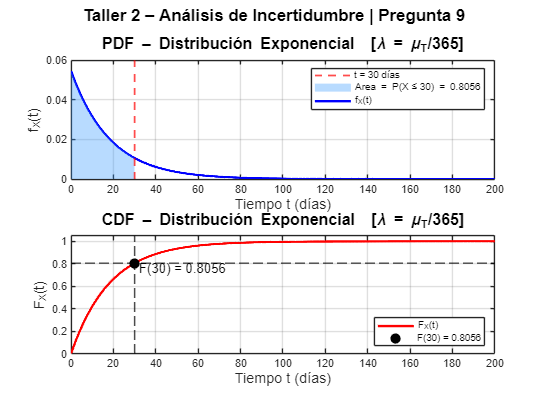

fprintf('\n');

% --- Gráficas PDF y CDF ---------------------------------
t = linspace(0, 200, 2000);      % días

f_t = lambda_exp * exp(-lambda_exp * t);   % PDF
F_t = 1 - exp(-lambda_exp * t);            % CDF

figure('Name','Pregunta 9 – Distribución Exponencial', ...
       'Position',[100 100 900 650]);

% ---- Subplot 1: PDF ------------------------------------
subplot(2,1,1);
plot(t, f_t, 'b-', 'LineWidth', 2);
hold on;
area(t(t<=30), f_t(t<=30), 'FaceColor',[0.2 0.6 1], ...
     'FaceAlpha',0.35, 'EdgeColor','none');
xline(30, '--r', 'LineWidth', 1.5);
hold off;
xlabel('Tiempo t (días)', 'FontSize', 12);
ylabel('f_X(t)', 'FontSize', 12);
title('PDF – Distribución Exponencial  [\lambda = \mu_T/365]', ...
      'FontSize', 13, 'FontWeight','bold');
legend('f_X(t)', sprintf('Área = P(X\\leq30) = %.4f', P_exp_le30), ...
       't = 30 días', 'Location','northeast');
grid on; box on;

% ---- Subplot 2: CDF ------------------------------------
subplot(2,1,2);
plot(t, F_t, 'r-', 'LineWidth', 2);
hold on;
plot(30, P_exp_le30, 'ko', 'MarkerSize', 8, 'MarkerFaceColor','k');
xline(30, '--k', 'LineWidth', 1.2);
yline(P_exp_le30, '--k', 'LineWidth', 1.2);
text(32, P_exp_le30 - 0.04, ...
     sprintf('F(30) = %.4f', P_exp_le30), 'FontSize', 11);
hold off;
xlabel('Tiempo t (días)', 'FontSize', 12);
ylabel('F_X(t)', 'FontSize', 12);
title('CDF – Distribución Exponencial  [\lambda = \mu_T/365]', ...
      'FontSize', 13, 'FontWeight','bold');
legend('F_X(t)', sprintf('F(30) = %.4f', P_exp_le30), ...
       'Location','southeast');
ylim([0 1.05]);
grid on; box on;

sgtitle('Taller 2 – Análisis de Incertidumbre | Pregunta 9', ...
        'FontSize', 14, 'FontWeight', 'bold');

**PUNTO 1: Calcule el número promedio anual de terremotos y su desviación estándar.**

El valor promedio obtenido es μ = **19.93 terremotos/año**, lo que indica que, en promedio, ocurren cerca de 20 eventos anuales. La desviación estándar es σ = **7.1837 terremotos/año**, lo cual es relativamente alta respecto a la media. Esto evidencia una variabilidad significativa entre años, indicando que el número de terremotos puede fluctuar considerablemente alrededor del promedio.

**PUNTO 2: Calcule la probabilidad de 2 terremotos en un mes**

La probabilidad obtenida es P(X=2) = **0.269228**, lo que indica que existe un 26.92% de probabilidad de que ocurran exactamente dos terremotos en un mes. Este valor es relativamente alto, lo que sugiere que este escenario es bastante probable bajo el modelo binomial. Esto se debe a que la probabilidad diaria p = **0.054603** no es tan pequeña, lo que incrementa la probabilidad de ocurrencias múltiples en 30 días.

**PUNTO 3: ¿Cuál es la probabilidad de que el primer terremoto ocurra en el día 15?**

La probabilidad calculada es P(Y=15) = **0.024878**, lo que indica que hay un 2.49% de probabilidad de que el primer terremoto ocurra exactamente en ese día. Este valor bajo refleja que es poco probable que el sistema permanezca sin eventos durante 14 días consecutivos y que el primer evento ocurra justo en el día 15, confirmando el comportamiento decreciente de la distribución geométrica.

**PUNTO 4: Determine el valor esperado y la desviación estándar del tiempo hasta el primer terremoto.**

El valor esperado es E[Y] = **18.3141 días**, lo que indica que en promedio el primer terremoto ocurre dentro de las primeras tres semanas del año. La desviación estándar es σ = **17.8071 días**, muy cercana al valor esperado, lo que evidencia una alta dispersión. Esto significa que, aunque el promedio es alrededor de 18 días, el evento puede ocurrir en un rango amplio de tiempo, reflejando una elevada incertidumbre en el momento de ocurrencia.

**PUNTO 5: ¿Cuál es la probabilidad de que el segundo terremoto ocurra en el día 30?**

La probabilidad obtenida es P(W₂=30) = **0.017949**, lo que indica que existe un 1.79% de probabilidad de que el segundo terremoto ocurra exactamente en ese día. Este valor es bajo, lo cual es consistente con la naturaleza del modelo binomial negativo, ya que se requiere una secuencia específica de ocurrencias previas. Esto confirma que la predicción exacta de eventos en días puntuales es altamente improbable.

**PUNTO 6: Determine el número esperado de días hasta que ocurran 4 terremotos.**

El valor esperado obtenido es E[W₄] = **73.2564 días**, lo que indica que, en promedio, se requieren aproximadamente dos meses y medio para que ocurran cuatro terremotos. Este resultado es coherente con la probabilidad diaria (p = 0.054603), mostrando que la acumulación de eventos toma tiempo debido a la baja frecuencia de ocurrencia diaria.

**PUNTO 7: Use un modelo de Poisson para calcular probabilidades de ocurrencia de terremotos.**

Para un mes, la probabilidad de exactamente dos terremotos es P(X=2) = **0.260754**, lo cual es relativamente alta y consistente con la tasa mensual λ = **1.638082**. Esto indica que dos eventos en un mes es un escenario bastante representativo del comportamiento promedio.

Para tres meses, la probabilidad acumulada de seis terremotos o menos es P(X≤6) = **0.774612**, lo que indica que hay un 77.46% de probabilidad de no superar este número de eventos en ese intervalo. Esto refleja que, aunque el número esperado de eventos aumenta con el tiempo, valores muy altos siguen siendo menos probables.

**PUNTO 8: Calcule media, varianza, desviación estándar, coeficiente de variación y asimetría.**

Los valores obtenidos son: media = **1.638082**, varianza = **1.638082**, desviación estándar = **1.279876**, coeficiente de variación = **0.781326** y asimetría = **0.781326**.

Esto confirma que la distribución de Poisson presenta igualdad entre media y varianza. El coeficiente de variación indica una dispersión moderada en relación con la media, mientras que la asimetría positiva evidencia una distribución sesgada hacia la derecha, característica de procesos de conteo de eventos poco frecuentes.

**PUNTO 9: Calcule la probabilidad de que transcurra un tiempo menor o igual a un mes sin que ocurra un terremoto.**

La probabilidad obtenida es P(X ≤ 30 días) = **0.805648**, lo que indica que existe un 80.56% de probabilidad de que ocurra al menos un terremoto dentro de un mes. Esto demuestra que, aunque la probabilidad diaria es baja, en intervalos de tiempo más largos la ocurrencia de eventos es altamente probable. Este comportamiento es consistente con la distribución exponencial, la cual modela tiempos entre eventos en procesos de Poisson.